n = size(A,1);
A_hat   = [A zeros(n,1);...
          -C    0     ]

A_hat = 1.0e+05 *

   -0.2141   -4.0746         0         0
    0.0000         0         0         0
         0    0.0000         0         0
         0         0   -0.9669         0


B_hat   = [B; 
           0];
Br      = [zeros(n,1); 1];
C_hat   = [C 0];
ss_hat = minreal(ss(A_hat,B_hat,C_hat,D));

1 state removed.


A_min = ss_hat.A

A_min = 1.0e+05 *

   -0.2141   -4.0746         0
    0.0000         0         0
         0    0.0000         0


B_min = ss_hat.B

B_min =      1
     0
     0


C_min = ss_hat.C

C_min = 1.0e+04 *

         0         0    9.6692


% Parameters
X_u     = 0;
X_uu    = 22.7841;
m       = 5037.7;

% Equilibrium point x0
x0      = 20*1.852/3.6;        % Longitudinal linear velocity in m/s
u0      = X_u*x0 + X_uu*x0^2;  % Thrust in N

% Linearize system around x0
A       = -(X_u/m + 2*X_uu/m*x0)

A = -0.0931

B       = 1/m

B = 1.9850e-04

C       = 1;
D       = 0;

% System order
n       = size(A,1);

% Open loop system
sys_ol  = ss(A,B,C,D);
Gp      = tf(sys_ol)


Gp =
 
   0.0001985
  -----------
  s + 0.09307
 
Continuous-time transfer function.
Model Properties


openloopPoles = eig(A);

% Augmented system with the integral of the error
A_hat   = [A zeros(n,1);...
          -C    0     ];
B_hat   = [B; 
           0];
Br      = [zeros(n,1); 1];
C_hat   = [1 zeros(1,n)];
D_hat   = 0;

% Q R matrices
Q       = 1000*(C'*C);
R       = 0.5e-3;

% Feedback gain
K_hat   = lqr(A_hat, B_hat,Q,R)

K_hat = 1.0e+03 *

    3.5893   -1.4142


K       =  K_hat(1);
ki      = -K_hat(2);

% Scaling matrix
% Nbar = rscale(sys_ol,K)

% Closed loop system
AA      = [A-B*K, B*ki; 
          -C,       0];
BB      = Br;
CC      = [C 0];
DD      = 0;
sys_cl  = ss(AA, BB, CC, DD);

A-B*K

ans = -0.8056

B*ki

ans = 0.2807

Gcl     = tf(sys_cl)


Gcl =
 
          0.2807
  -----------------------
  s^2 + 0.8056 s + 0.2807
 
Continuous-time transfer function.
Model Properties


% steady-state response
ssr     = dcgain(Gcl)

ssr = 1

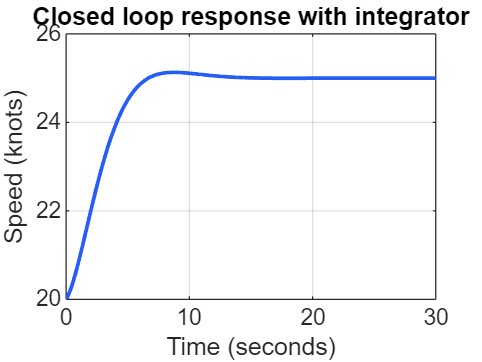


% Time vector
t       = 0:0.1:30;

% Control input
u       = u0*ones(size(t));

% Reference setpoint
r0      = 25*1.852/3.6;
r       = r0*ones(size(t));

% Initial states
z0      = (u0 + K*x0)/ki + (r0 - x0);
x0_hat  = [x0, z0];

% Simulate the response of the system
[y, t, x_hat] = lsim(sys_cl, r, t, x0_hat);

figure
plot(t, y*3.6/1.852, 'k', 'LineWidth', 1.5, 'Color', '#265EF5')
xlabel('Time (seconds)')
ylabel('Speed (knots)')
title('Closed loop response with integrator')
grid on

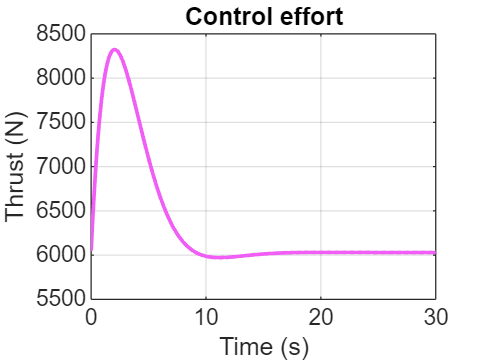

% Control effort (Thrust)
u_effort = -K*x_hat(:,1) + ki*x_hat(:,2);

figure
plot(t, u_effort, 'LineWidth', 1.5, 'Color', '#F15EF5'), grid on
xlabel('Time (s)')
ylabel('Thrust (N)')
title('Control effort')